# Duvidas gerais

clear all;
clc;
close all;


## Interpretação do zero e da frequência complexa

Frequência complexa


$$x(t) = e^{st}
$$



$$x(t) = e^{-t} cos(t)$$



$$s = -1 \pm j$$


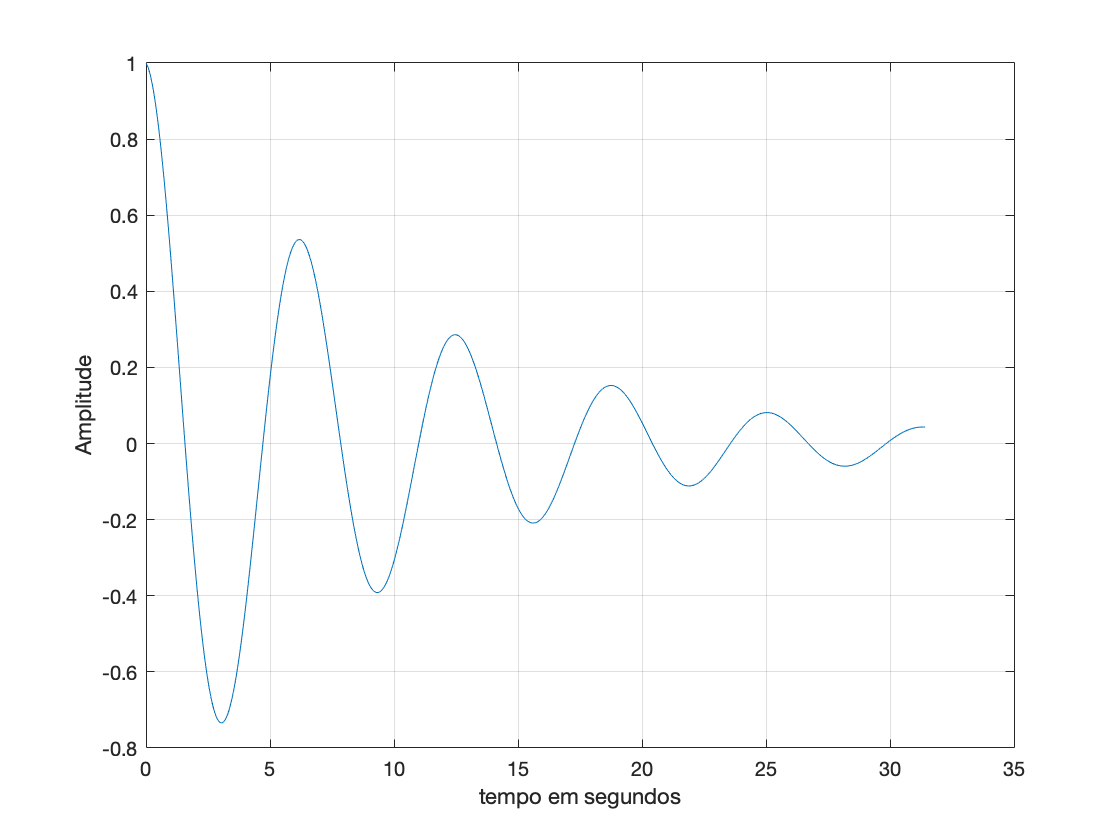

% Criando a função no tempo

w     = 1;
T     =  2*pi/w;
tempo = linspace(0,10*T,1000);
x     = exp(-0.1*tempo).*cos(-tempo);

figure()
plot(tempo,x);
grid;
xlabel('tempo em segundos')
ylabel('Amplitude')

## Função de transferência - H(s)


% s = -0.1 +/- j

z1 = -0.1 + j*60*2*pi;      % w = 1
z2 = -0.1 - j*60*2*pi;      % w = 1

p1 = -1;
p2 = -2;

k  =  1;

H = zpk([z1 z2], [p1 p2], k)

H =
 
  (s^2 + 0.2s + 1.421e05)
  -----------------------
        (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



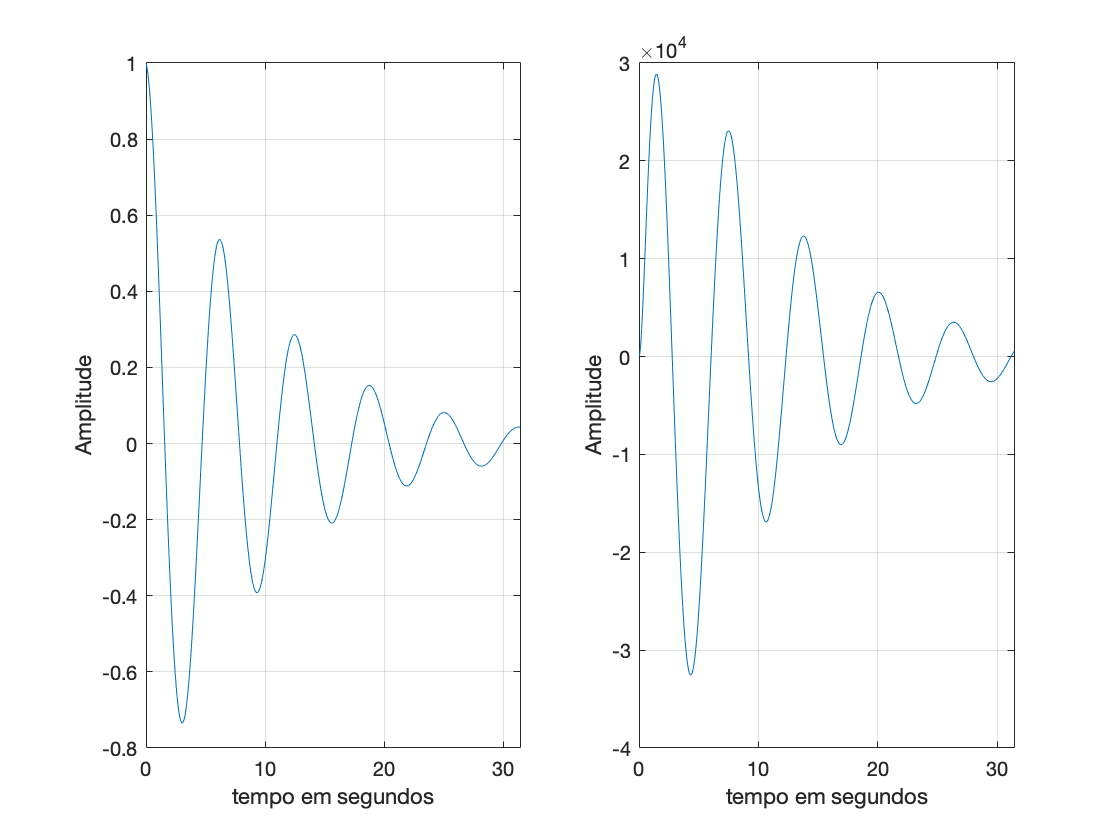

y = lsim(H,x,tempo);
figure()
subplot(1,2,1)
plot(tempo,x);
grid;
xlabel('tempo em segundos')
ylabel('Amplitude')
subplot(1,2,2)
plot(tempo,y);
grid;
xlabel('tempo em segundos')
ylabel('Amplitude')

## Resposta em frequência - Fourier

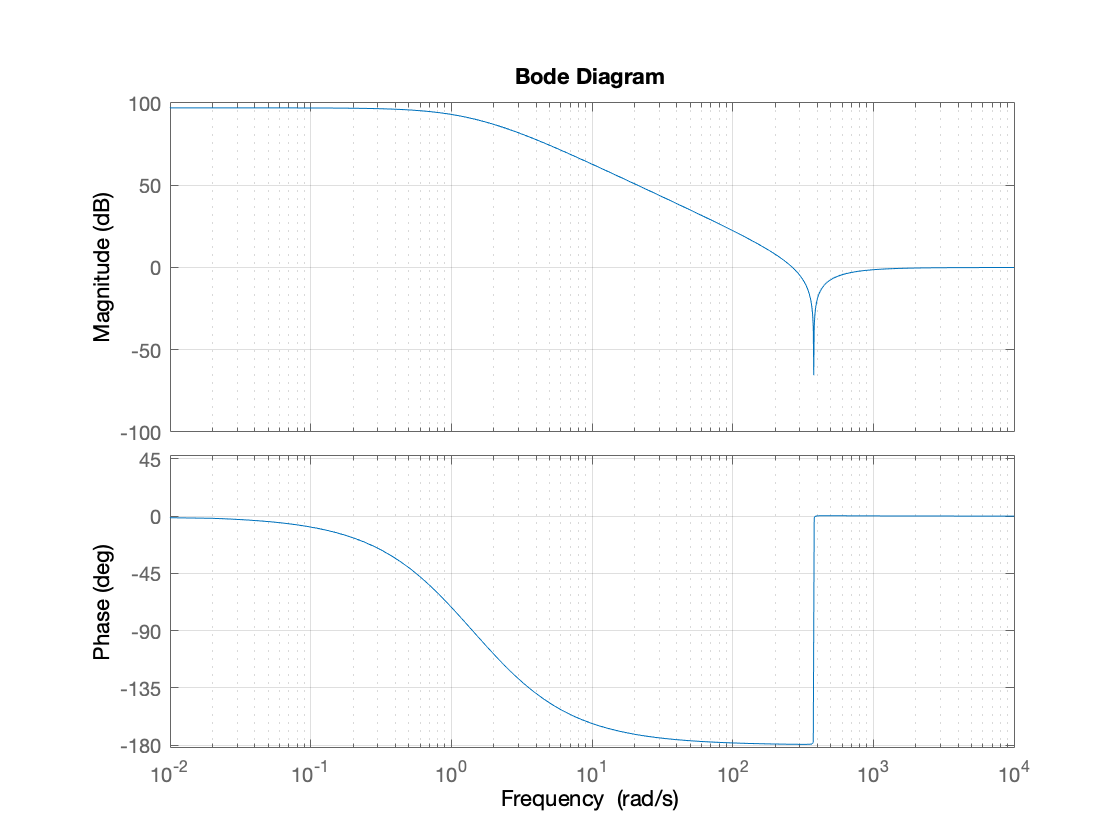

figure()
bode(H);
grid;

## Sinal discreto

N = 1;
D = [1 1];

H = tf(N,D)

H =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



Hw = @(w)  1./(j*w + 1)

Hw = function_handle with value:
    @(w)1./(j*w+1)


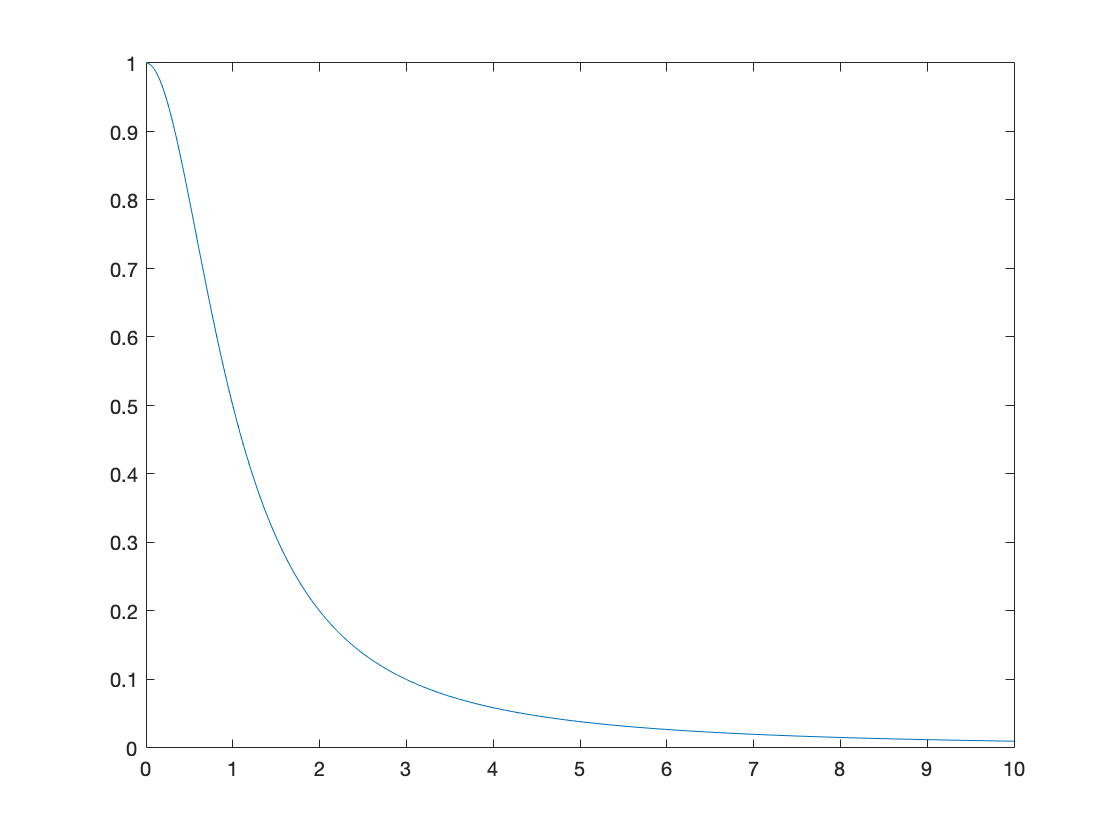

w = linspace(0,10,1000);

figure()

plot(w,Hw(w))

ws = 2 * 5;

Ts = 2*pi/ws

Ts = 0.6283


% Aplicando a bilinear

[Nd,Dd] = bilinear(N,D,1/Ts)

Nd =     0.2391    0.2391


Dd =     1.0000   -0.5219


Hz = tf(Nd,Dd,Ts)

Hz =
 
  0.2391 z + 0.2391
  -----------------
     z - 0.5219
 
Sample time: 0.62832 seconds
Discrete-time transfer function.



## Convolução